% Hard coded parameters
b = 50; % baseline [mm]
f = 10; % focal length [mm]
ps = 0.006; % pixel size [mm]
xNumPix = 752; % number of pixels in the x direction of the sensor [px]
cxLeft = xNumPix/2; % left camera x center [px]
cxRight = xNumPix/2; % right camera x center [px]

% create two cameras
Cam_L = SE3(0, 0, 0);
Cam_R = SE3(b, 0, 0);

% Create the ball
Z_b = linspace(.5, 10, 100); %
BALL = repmat(SE3(), 1, numel(Z_b));   % preallocate exactly 100
for i = 1:numel(Z_b)
    BALL(i) = SE3(0, 0, Z_b(i));
end
    
% see the ball
BALL_L = inv(Cam_L) * BALL;
BALL_R = inv(Cam_R) * BALL;

% find the balls position from the cameras
pL = transl(BALL_L).';
pR = transl(BALL_R).';

XL = pL(1,:)

XL =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ZL = pL(3,:)

ZL =     0.5000    0.5960    0.6919    0.7879    0.8838    0.9798    1.0758    1.1717    1.2677    1.3636    1.4596    1.5556    1.6515    1.7475    1.8434    1.9394    2.0354    2.1313    2.2273    2.3232    2.4192    2.5152    2.6111    2.7071    2.8030    2.8990    2.9949    3.0909    3.1869    3.2828    3.3788    3.4747    3.5707    3.6667    3.7626    3.8586    3.9545    4.0505    4.1465    4.2424    4.3384    4.4343    4.5303    4.6263    4.7222    4.8182    4.9141    5.0101    5.1061    5.2020



XR = pR(1,:)

XR =    -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50   -50


ZR = pR(3,:)

ZR =     0.5000    0.5960    0.6919    0.7879    0.8838    0.9798    1.0758    1.1717    1.2677    1.3636    1.4596    1.5556    1.6515    1.7475    1.8434    1.9394    2.0354    2.1313    2.2273    2.3232    2.4192    2.5152    2.6111    2.7071    2.8030    2.8990    2.9949    3.0909    3.1869    3.2828    3.3788    3.4747    3.5707    3.6667    3.7626    3.8586    3.9545    4.0505    4.1465    4.2424    4.3384    4.4343    4.5303    4.6263    4.7222    4.8182    4.9141    5.0101    5.1061    5.2020



xLeft = cxLeft + (f *(XL./ZL))

xLeft =    376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376   376


xRight = cxRight + (f *(XR./ZR))

xRight =  -624.0000 -462.9831 -346.6277 -258.6154 -189.7143 -134.3093  -88.7887  -50.7241  -18.4223    9.3333   33.4394   54.5714   73.2477   89.8728  104.7671  118.1875  130.3424  141.4028  151.5102  160.7826  169.3194  177.2048  184.5106  191.2985  197.6216  203.5261  209.0523  214.2353  219.1062  223.6923  228.0179  232.1047  235.9717  239.6364  243.1141  246.4188  249.5632  252.5586  255.4153  258.1429  260.7497  263.2437  265.6321  267.9214  270.1176  272.2264  274.2528  276.2016  278.0772  279.8835



%Equations to find depth
d = abs((xLeft - cxLeft)-(xRight-cxRight))*ps;
Z = (b * f)./d;
fprintf("d = %f , Z = %f", d, Z);

d = 6.000000 , Z = 5.033898d = 4.335766 , Z = 3.807692d = 3.394286 , Z = 3.061856d = 2.788732 , Z = 2.560345d = 2.366534 , Z = 2.200000d = 2.055363 , Z = 1.928571d = 1.816514 , Z = 1.716763d = 1.627397 , Z = 1.546875d = 1.473945 , Z = 1.407583d = 1.346939 , Z = 1.291304d = 1.240084 , Z = 1.192771d = 1.148936 , Z = 1.108209d = 1.070270 , Z = 1.034843d = 1.001686 , Z = 0.970588d = 0.941363 , Z = 0.913846d = 0.887892 , Z = 0.863372d = 0.840170 , Z = 0.818182d = 0.797315 , Z = 0.777487d = 0.758621 , Z = 0.740648d = 0.723508 , Z = 0.707143d = 0.691502 , Z = 0.676538d = 0.662207 , Z = 0.648472d = 0.635294 , Z = 0.622642d = 0.610483 , Z = 0.598790d = 0.587537 , Z = 0.576699d = 0.566254 , Z = 0.556180d = 0.546458 , Z = 0.537071d = 0.528000 , Z = 0.519231d = 0.510748 , Z = 0.502538d = 0.494588 , Z = 0.486885d = 0.479419 , Z = 0.472178d = 0.465153 , Z = 0.458333d = 0.451711 , Z = 0.445277d = 0.439024 , Z = 0.432945d = 0.427031 , Z = 0.421277d = 0.415675 , Z = 0.410221d = 0.404908 , Z = 0.399731d


% Debug sizes (very helpful)
fprintf("size(Z_b) = %s\n", mat2str(size(Z_b)));

size(Z_b) = [1 100]


fprintf("size(d)   = %s\n", mat2str(size(d)));

size(d)   = [1 100]


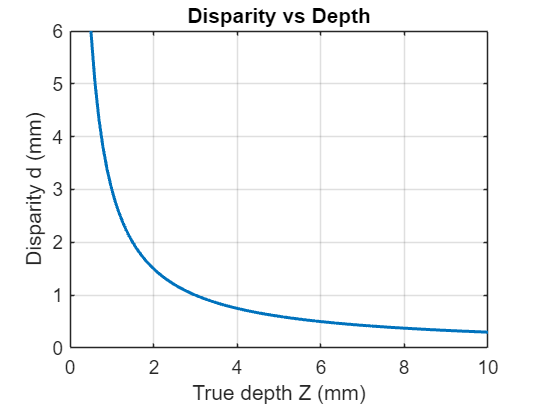


figure;
plot(Z_b(:), d(:), 'LineWidth', 1.5);
xlabel('True depth Z (mm)');
ylabel('Disparity d (mm)');
title('Disparity vs Depth');
grid on;